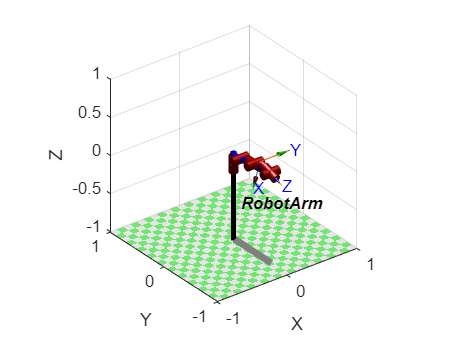

% Script that calculates the required force in each joint to lift an
% object of 1 kg(9.81 Newton) to its maximum extent in the y-direction. 

clear, close all;

L1 = 0.162575;
L1_d = 0.112;
L1_a = 0.117839;
L2 = 0.28;
L3 = 0.186904;
L4 = 0.109554;
L5 = 0.08561; 
L6 = 0.116047;

% Link Offsets
L2_offset = 2.35619;
L3_offset = -0.7853734;
L5_offset = 0.68033;

% Creatin Links with DH - parameters
L(1) = Link('d',L1_d,'a',L1_a,'alpha',pi/2,'offset',0);
L(2) = Link('d',0,'a',L2,'alpha',0,'offset',L2_offset);
L(3) = Link('d',0,'a',0,'alpha',pi/2,'offset',L3_offset);
L(4) = Link('d',L3+L4,'a',0,'alpha',pi/2,'offset',0);
L(5) = Link('d',0,'a',0,'alpha',pi/2,'offset',L5_offset+pi);
L(6) = Link('d',-(L5+L6),'a',0,'alpha',0,'offset',0);

RobotArm = SerialLink(L,'name', 'RobotArm');

% Maximum posture for the robotArm in world y-direction, found with plot.teach
qn_MaxLenght = [deg2rad(-90) deg2rad(-122.4) deg2rad(126) deg2rad(0) deg2rad(-18) deg2rad(0)];

% Plots the arm in maximum posture above.
RobotArm.plot(qn_MaxLenght)


% calculates the force needet to lift an object on 1 Kg = 9.81 Newton in z direction.
W0 = [0; 0; 10; 0; 0; 0];
Q = RobotArm.jacob0(qn_MaxLenght)' * W0;
ForceNeedInJoints = Q'

ForceNeedInJoints =    -0.0000    3.7668    1.0342    0.0000    1.9245         0
